# 相关性分析

% 清除命令窗口和工作区
clc;
clear;

% 读取 Excel 文件中的数据
or_data = xlsread('base_crab_1.xlsx');

% 分离标签和指标值
sed = or_data(:, 6); % 第 6 列为 sed
crab = or_data(:, 7); % 第 7 列为 crab
sed2 = or_data(:, 8);  % 第 8 列为 sed2
crab2 = or_data(:, 9); % 第 9 列为 crab2
sed3 = or_data(:, 10); % 第 10 列为 sed3
crab3 = or_data(:, 11); % 第 11 列为 crab3

% 删除包含 NaN 值的行
valid_idx = ~isnan(sed) & ~isnan(crab);
sed = sed(valid_idx);
crab = crab(valid_idx);
valid_idx2 = ~isnan(sed2) & ~isnan(crab2);
sed2 = sed2(valid_idx2);
crab2 = crab2(valid_idx2);
valid_idx3 = ~isnan(sed3) & ~isnan(crab3);
sed3 = sed(valid_idx3);
crab3 = crab(valid_idx3);

% 标准化指标值
sed_normalized = zscore(sed);
crab_normalized = zscore(crab);

% 计算 sed 和 crab 之间的相关系数和 p 值
[r_CORR, p_CORR] = corr(sed, crab);
[r_CORR2, p_CORR2] = corr(sed2, crab2);
[r_CORR3, p_CORR3] = corr(sed3, crab3);

## 多子图拟合

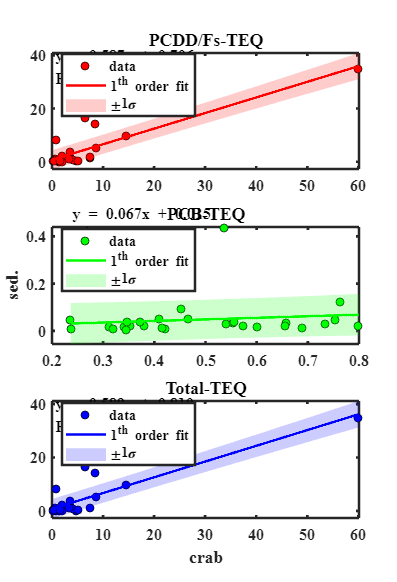

% 清除当前图形
clf;

% 设置字体和加粗
fontName = 'Times New Roman';
fontSize = 12;
fontWeight = 'bold';

% 第一个子图
subplot(3, 1, 1);
h(1) = plot(crab, sed, 'ko', 'MarkerFaceColor', 'r');
% 拟合多项式
p1 = polyfit(crab, sed, 1);
% 计算拟合值
yfit1 = polyval(p1, crab);
% 计算 R^2 值
SStot = sum((sed - mean(sed)).^2);
SSres = sum((sed - yfit1).^2);
r2_1 = 1 - SSres/SStot;
% 显示拟合曲线和误差带
h(2:3) = polyplot(crab, sed, 1, 'r', 'error', 'alpha');
set(h(2), 'LineWidth', 2);
set(h(3), 'LineWidth', 2);
legend(h, 'data', '1^{th} order fit', '\pm1\sigma', 'location', 'best');
% 显示拟合公式和 R^2 值
text(min(crab), max(sed), sprintf('y = %.3fx + %.3f\nR^2 = %.3f', p1(1), p1(2), r2_1), 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
title('PCDD/Fs-TEQ', 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
set(gca, 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight, 'LineWidth', 2);

% 第二个子图
subplot(3, 1, 2);
h(1) = plot(crab2, sed2, 'ko', 'MarkerFaceColor', 'g');
% 拟合多项式
p2 = polyfit(crab2, sed2, 1);
% 计算拟合值
yfit2 = polyval(p2, crab2);
% 计算 R^2 值
SStot = nansum((sed2 - nanmean(sed2)).^2);
SSres = nansum((sed2 - yfit2).^2);
r2_2 = 1 - SSres/SStot;
% 显示拟合曲线和误差带
h(2:3) = polyplot(crab2, sed2, 1, 'g', 'error', 'alpha');
set(h(2), 'LineWidth', 2);
set(h(3), 'LineWidth', 2);
legend(h, 'data', '1^{th} order fit', '\pm1\sigma', 'location', 'best');
% 显示拟合公式和 R^2 值
text(min(crab2), max(sed2), sprintf('y = %.3fx + %.3f\nR^2 = %.3f', p2(1), p2(2), r2_2), 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
title('PCB-TEQ', 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
ylabel('sed.', 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
set(gca, 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight, 'LineWidth', 2);

% 第三个子图
subplot(3, 1, 3);
h(1) = plot(crab3, sed3, 'ko', 'MarkerFaceColor', 'b');
% 拟合多项式
p3 = polyfit(crab3, sed3, 1);
% 计算拟合值
yfit3 = polyval(p3, crab3);
% 计算 R^2 值
SStot = nansum((sed3 - nanmean(sed3)).^2);
SSres = nansum((sed3 - yfit3).^2);
r2_3 = 1 - SSres/SStot;
% 显示拟合曲线和误差带
h(2:3) = polyplot(crab3, sed3, 1, 'b', 'error', 'alpha');
set(h(2), 'LineWidth', 2);
set(h(3), 'LineWidth', 2);
legend(h, 'data', '1^{th} order fit', '\pm1\sigma', 'location', 'best');
% 显示拟合公式和 R^2 值
text(min(crab3), max(sed3), sprintf('y = %.3fx + %.3f\nR^2 = %.3f', p3(1), p3(2), r2_3), 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
title('Total-TEQ', 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
xlabel('crab', 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight);
set(gca, 'FontName', fontName, 'FontSize', fontSize, 'FontWeight', fontWeight, 'LineWidth', 2);


% 调整图像窗口大小位置
set(gcf, 'unit', 'centimeters', 'position', [1 2 15 22]);


## 绘图2

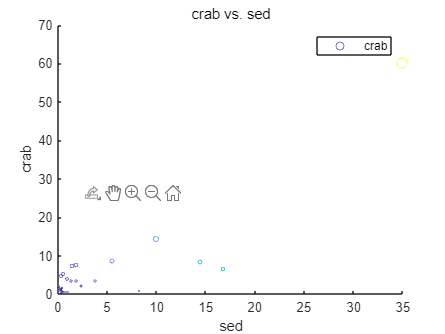

% 创建 sed 和 crab 的 scatter
s2 = scatter(sed,crab,crab,sed,"DisplayName","crab");

% 添加 xlabel, ylabel, title 和 legend
xlabel("sed")
ylabel("crab")
title("crab vs. sed")
legend

## 分析1